## Preset

img_rgb = imread(".\img_duplo.png"); % Liest das RGB-Bild von der Festplatte
img_bw = rgb2gray(img_rgb); % Konvertiert das RGB-Bild in ein Graustufenbild
img_binarized = imbinarize(img_bw);

## bwareaopen

% Entfernt alle verbundenen Komponenten (Objekte),
% die weniger als 50 Pixel in dem Graustufenbild img_bw haben.

img_open = bwareaopen(img_binarized, 50); % Wendet die Bereichsöffnung auf das binäre Bild an, um kleine Objekte zu entfernen

## bwmorph


img_morphed = bwmorph(img_binarized,'remove'); % Führt eine morphologische Operation (hier: Entfernen) auf dem binären Bild durch


## imerode

se = strel('disk', 8); % Erstellt ein strukturelles Element für die Dilatation (hier: eine Linie)

img_eroded = imerode(img_bw, se);


## bwdilate


% Skript F.240
img_dilated = imdilate(img_binarized, se); % Wendet die Dilatation auf das binäre Bild an


## edge


%img_edge = edge(img_binarized); % Findet Kanten im binären Bild
img_edge = edge(img_bw); % Findet Kanten im black/white Bild


## imclose

img_close = imclose(img_bw, se);


## imadjust


% Kontrast erhöhen mit imadjust
img_contrast_adjusted = imadjust(img_bw);


## Verbinden

% -> nach farben filtern, dann sind die schatten weg. dann weiter schauen
% dann erode benutzen um die nupsies zu eliminieren
img_hsv = rgb2hsv(img_rgb);

## bwconncomp

%img_CC = bwconncomp(img_bw)


## show Images

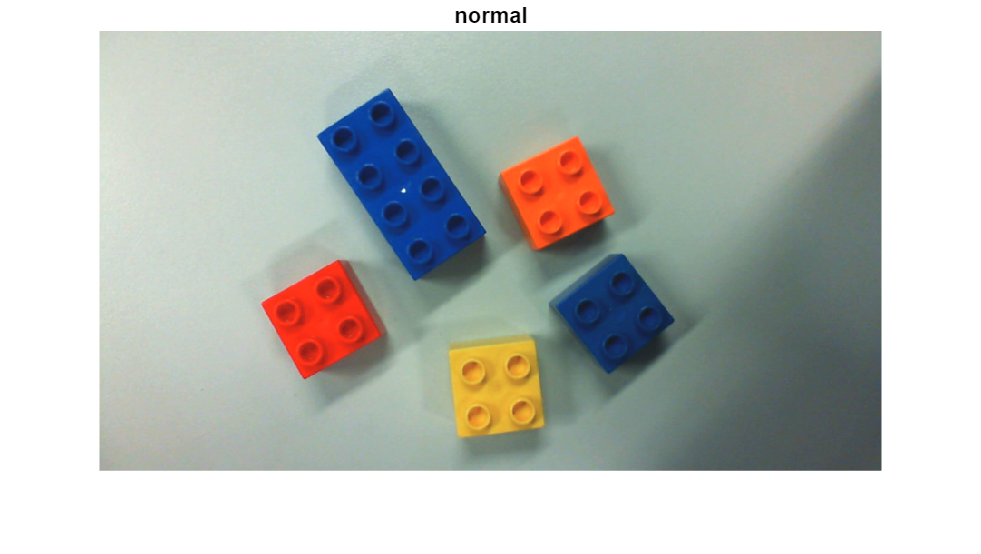

figure, imshow(img_rgb), title('normal') % Zeigt das Original-RGB-Bild in einem neuen Fenster an

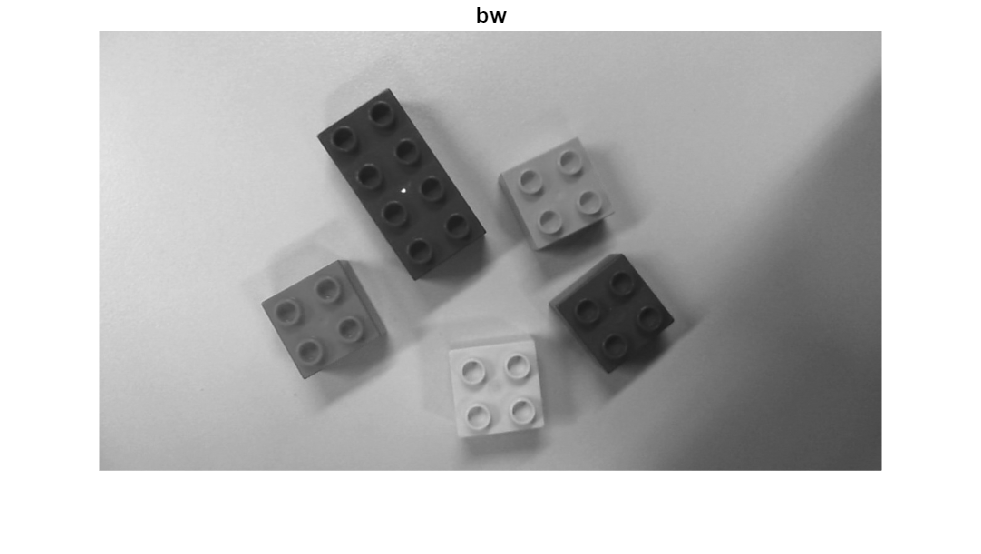

figure, imshow(img_bw), title('bw') % Zeigt das Graustufenbild in einem neuen Fenster an

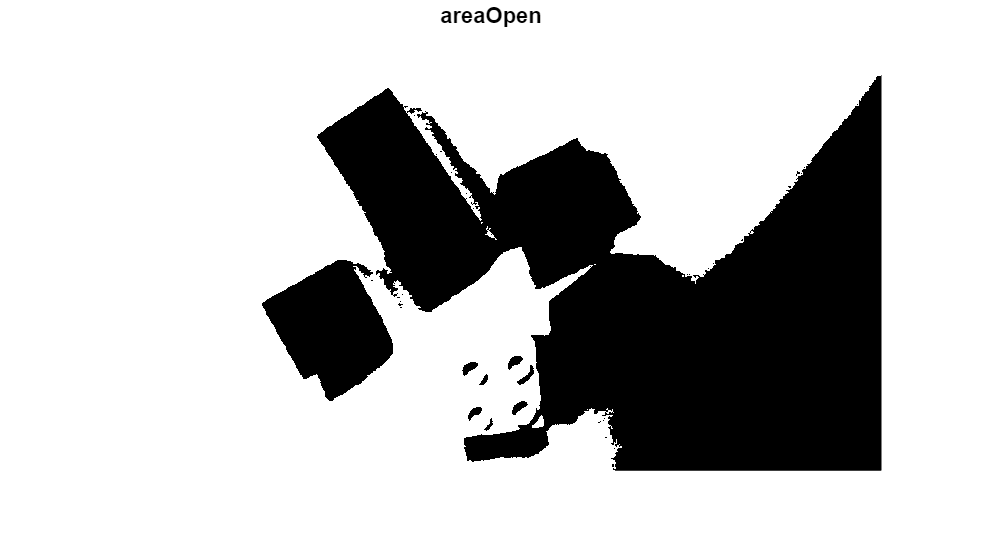

figure, imshow(img_open), title('areaOpen') % Zeigt das nach Bereichsöffnung bearbeitete Bild in einem neuen Fenster an

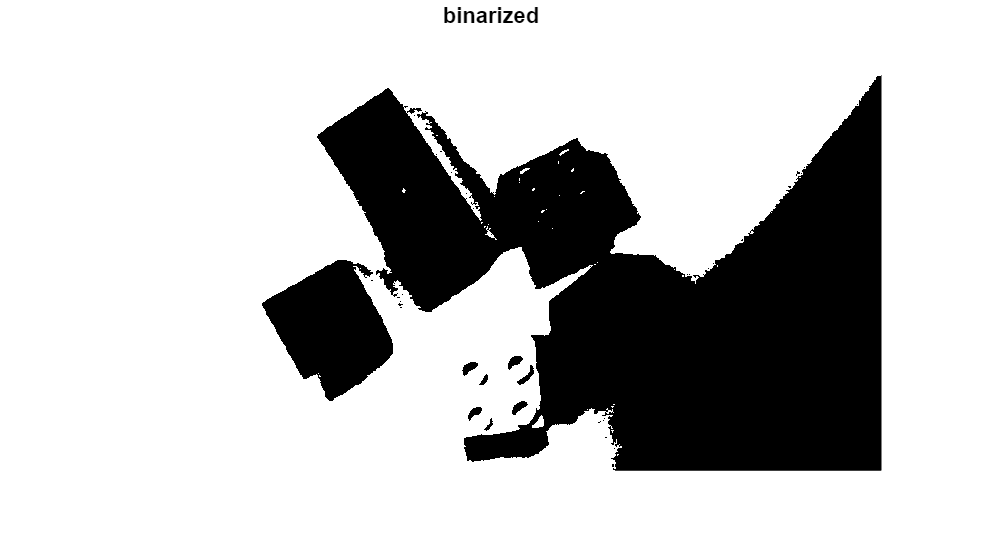

figure, imshow(img_binarized), title('binarized') % Zeigt das Graustufenbild in einem neuen Fenster an

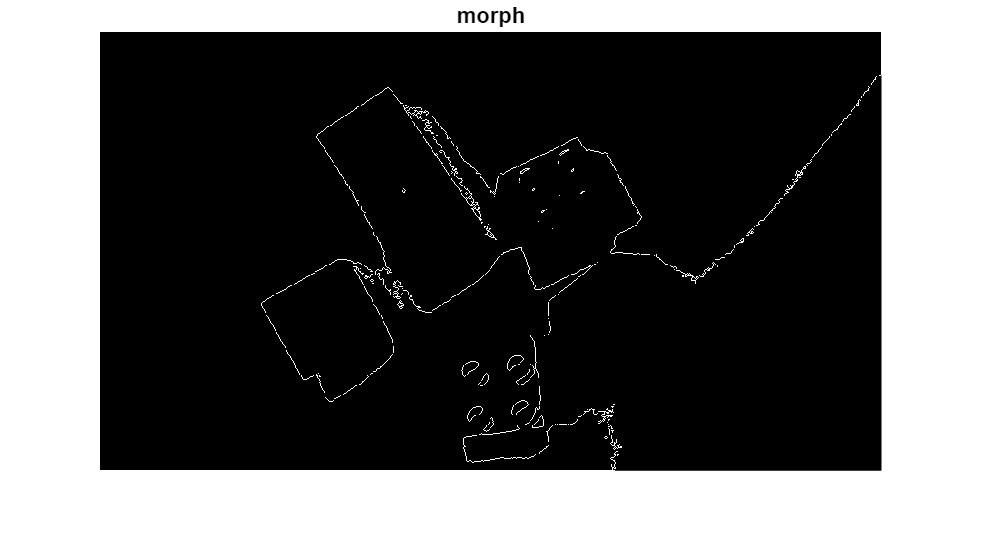

figure, imshow(img_morphed), title('morph') % Zeigt das morphologisch bearbeitete Bild in einem neuen Fenster an

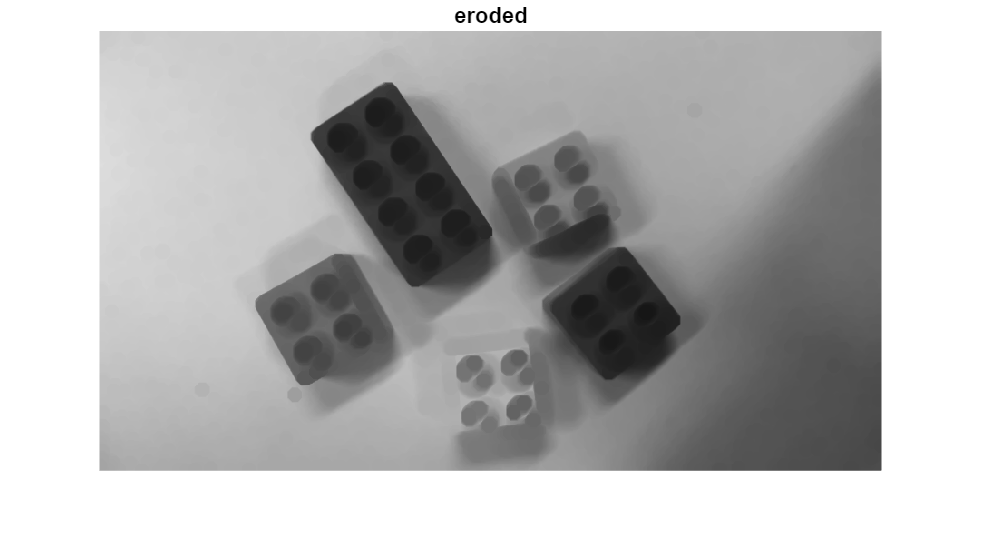

figure, imshow(img_eroded), title('eroded')

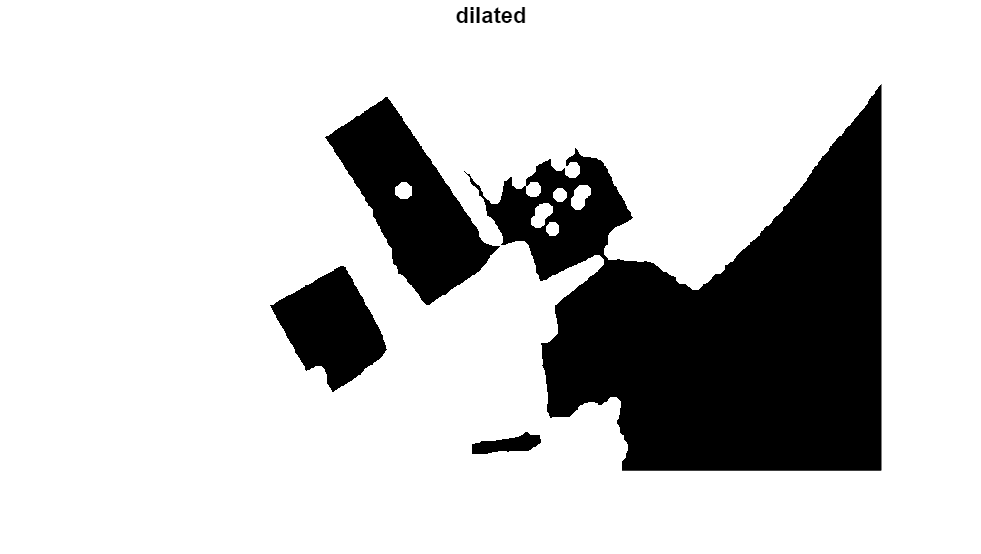

figure, imshow(img_dilated), title('dilated') % Zeigt das dilatierte Bild in einem neuen Fenster an

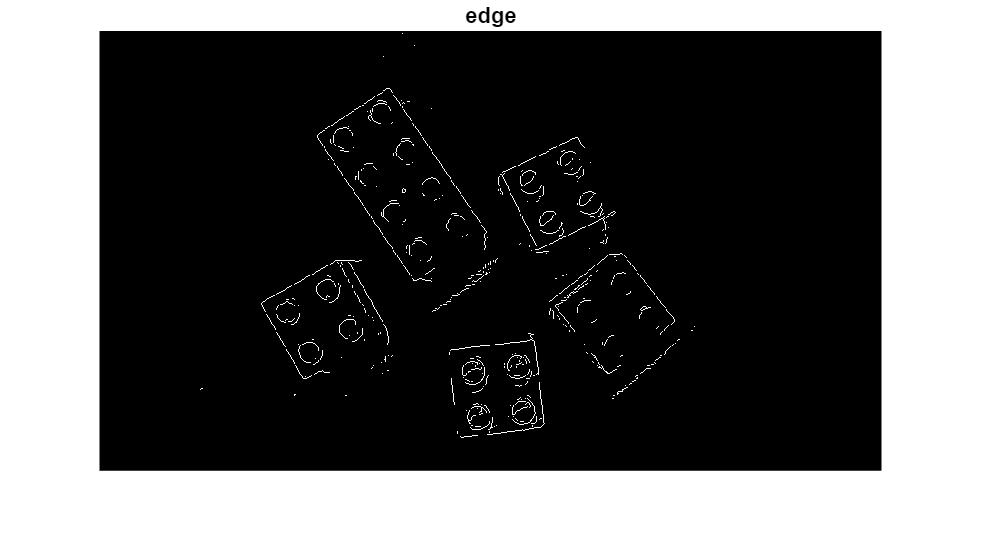

figure, imshow(img_edge), title('edge') % Zeigt das Bild mit hervorgehobenen Kanten in einem neuen Fenster an

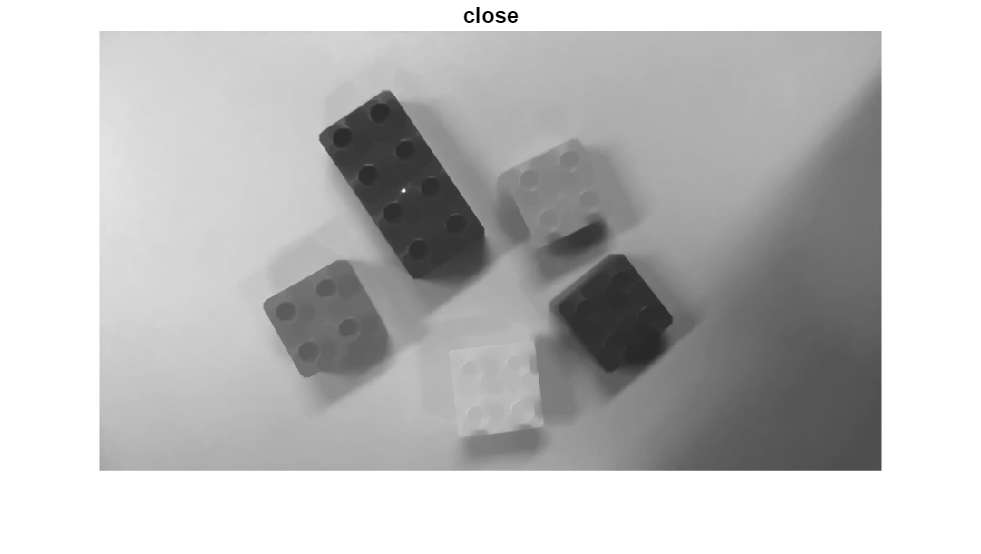

figure, imshow(img_close), title('close')

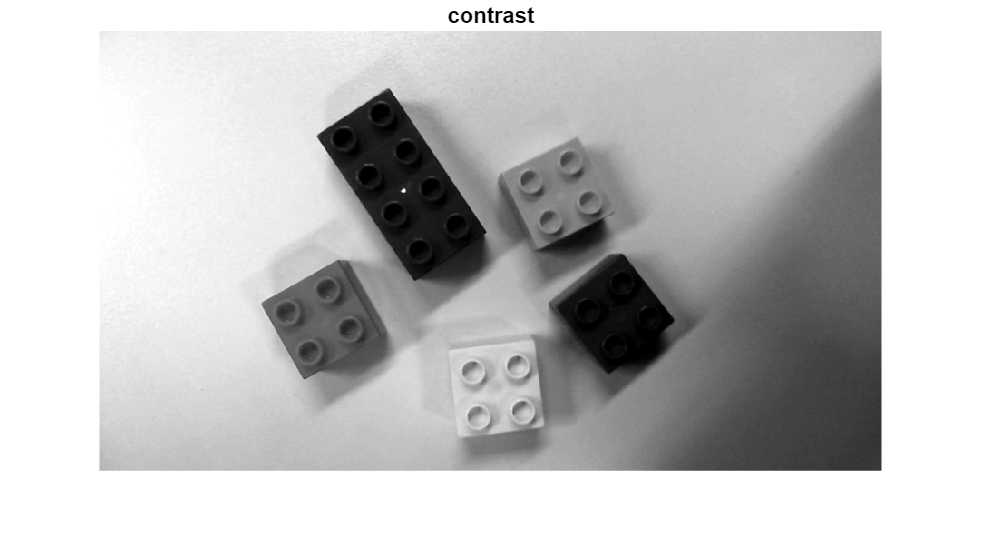

figure, imshow(img_contrast_adjusted), title('contrast')

figure, imshow(schritt_02), title('Ablauf') % Zeigt das Bild mit hervorgehobenen Kanten in einem neuen Fenster an

Unrecognized function or variable 'schritt_02'.